Piotr Sienkiewicz     324 887

Tadeusz Chmielik    324 856

# Sprawozdanie - optyczny system pomiaru tętna

Jednym ze sposobów pomiaru tętna jest czujnik optyczny badający zmianę natężenia światła przechodzącego przez tkanki w momencie przepływu krwi (w rytmie zgodnym z biciem serca). Zadanie polega na zarejestrowaniu a następnie przeanalizowaniu tego typu nagrania w celu wyznaczenia tętna.

## Rejestracja sygnału wejściowego

Do wykonania nagrania wykorzystano kamerę smartphona Iphone 15, zarejestrowano 10 sekundowy film w jakośći HD i 30 klatek/sekundę. Próbowano także wykonać film za pomocą smartfona Xiaomi Redmi Note 8 Pro, lecz wykonane przez niego nagrania zupełnie nie nadawały się do wykorzystania w tym zadaniu ze względu na bardzo małą czułość matrycy - na nagraniu nie było jakichkolwiek tętnień jasności.

## Przygotowanie danych do analizy

Wykorzytano poniższy kod do przygotowania danych do analizy.

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 300;
FPS = 30;

% wektor jasności
br = zeros(2, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader('data/movie4.mp4');
    % v = VideoReader('data/movie_4.MOV');
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    fig = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(fig/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);

W pętli dla każdej klatki filmu wybierano jedynie składową czerwoną, a następnie zapisywano punkt ze środka obrazu, zakładając, że tam najlepiej palec dotykał obiektywu aparatu. Następnie dla każdej klatki wyliczano średnią jasność wszystkich pikseli. Jest to typowy mechanizm redukcji szumów w przetwarzanym sygnale, taki sygnał jest bardziej odporny na przykład na nierówne ułożenie palca. Na koniec odejmowano składową stałą, którą wyznaczano na podstawie średniej jasności całego obrazu w czasie całego nagrania.

Po wyznaczeniu jasności można wyświetlić jej wykres - widać na nim wyraźnie cykliczne zmiany, które odpowiadają pulsowi. Dla pojedynczego punktu widać bardzo wyraźnie kwantyzację danych (skokowe zmiany wartości), wykreś wartości średniej jest dużo gładszy, a więc on zostanie wykorzystany do dalszej analizy.

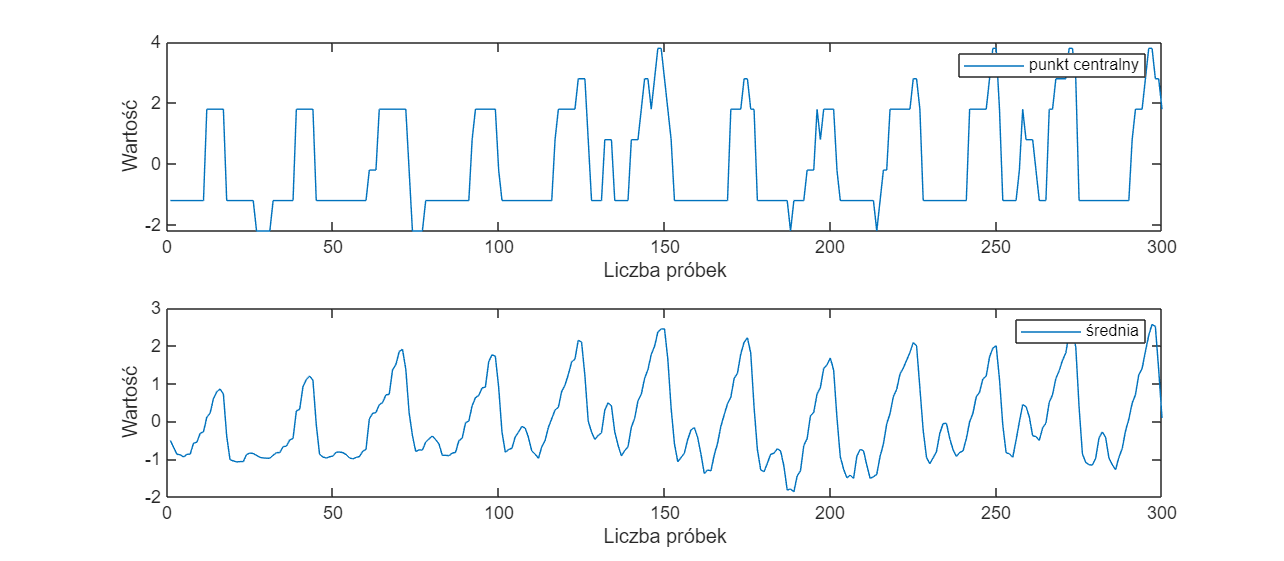

fig = figure();
set(fig,'Units','normalized','Position',[0 0 1 .7]);

subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny');
xlabel('Liczba próbek');
ylabel('Wartość');

subplot(2,1,2);
plot(br(2,:));
legend('średnia');
xlabel('Liczba próbek');
ylabel('Wartość');

## Zliczanie tętna

Do wyznaczenia tętna z otrzymanych przebiegów jasności wykorzystano funkcję *findpeaks* zliczjącą ekstrema lokalne. Jak widać na powyższym wykresie, każde uderzenie serca skutkuje powstaniem dwóch ekstremów na wykresie - dużego i małego. Dlatego aby liczyć rzeczywistą ilość uderzeń serca, ustawiono minimalną różnicę wielkości pików ponad sygnałem na 1.3. Następnie zliczono otrzymane ekstrema. Aby pomiar był jak najbardziej niezależny od długości nagrania, czas pomiaru jest liczony w ilości klatek *samples* między pierwszym a ostatnim ekstremum. Czas trwania jednej klatki wynosi 1/30 sekundy, natomiast okres jednego uderzenia serca w ilości klatek wynosi *samples / (counter - 1)*. Na tej podstawie wyznaczono okres jednego uderzenia *T* (w sekundach) oraz tętno *pulse*. W wyniku zastosowania tej metody na badanej próbie otrzymano 70,46 BPM.  

[values, locations] = findpeaks(br(2,:), "MinPeakProminence", 1.3);
counter = length(values);
samples = locations(end) - locations(1);
T = samples / (counter - 1) / FPS;


pulse = 60/T

pulse = 70.4626

## Wykres tętna

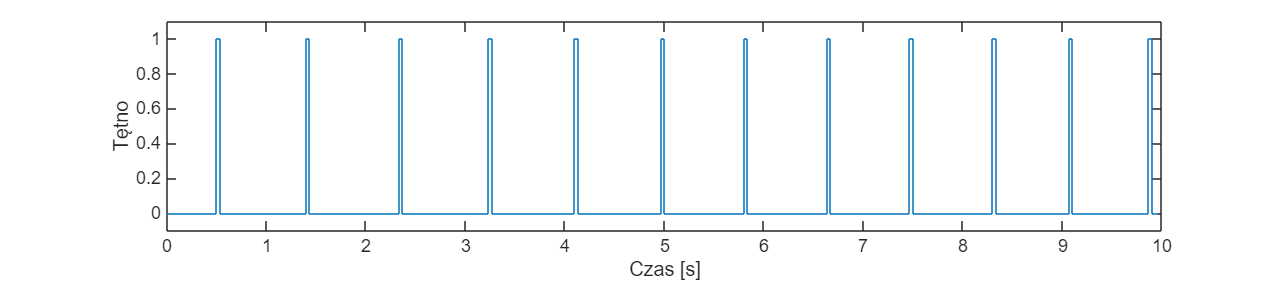

pulse_plot = zeros(size(br(2,:)));
pulse_plot(locations) = 1;

time = (0:length(br(2,:)) - 1) / FPS;

fig = figure();
set(fig,'Units','normalized','Position', [0 0 1 .35]);
stairs(time, pulse_plot);
ylim([-0.1 1.1]);
ylabel('Tętno');
xlabel('Czas [s]');

## Analiza rozdzielczości pomiaru

Jeżeli jako czynnik ograniczający rozdzielczość pomiaru przyjąć minimalny kwant czasu, który wynika z ilości klatek na sekundę, to minimalną rozdzielczość można wyliczyć następująco:


$$\frac{1}{FPS} \cdot \left( \frac{samples}{counter - 1} - \frac{samples - 1}{counter - 1} \right)$$


Gdzie *FPS* to ilość klatek na sekundę, *samples* to ilość próbek między pierwszym a ostatnim ekstremum, a *counter* to liczba ekstremów. 

1 / FPS * (samples / (counter - 1) - (samples - 1) / (counter - 1))

ans = 0.0030

Dla przypadku danych wykorzytywanych w zadaniu otrzymano 0,003BPM, co jest niezwykle dobrym wynikiem. Nie jest on jednak zaskakujący, gdy przyjmuje się taki sposób jego wyznaczania - jedna klatka trwa zaledwie około 33ms, ilość klatek jest dzielona przez liczbę ekstremów, a więc jeżeli rozdzielczość pomiaru wynika tylko z rozdzielczości czasu, to jest ona bardzo wysoka.

Jednak w praktyce nie oznacza to tak wielkiej dokładności wyników. Rejestrowane zmiany jasności są bardzo niewielkie, a pomiar jest wrażliwy na jakiekolwiek zakłócenia, sam sposób trzymania palca na obiektywie ma znaczenie. Może wystąpić sytuacja, że zamiana jasności wskutek jakiegoś zakłócenia zostanie potraktowana jako uderzenie serca. Podobnie podczas eksperymentów sprawdzono, że u jednego członka zespołu puls był ledwo wykrywalny, przez co nie dało się czasem określić poprawnie ekstremów, podczas gdy pomiar tą samą kamerą u drugiego członka zespołu dawał za każdym razem bardzo dobre wyniki. Tak więc mimo dużej wartości rozdzielczości, która wyszła w powyższych obliczeniach, pomiar nie jest idealny, aczkolwiek daje dobre wyniki jak na tak prostą metodę pomiarową bez użycia jakiejkolwiek przystosowanej do tego celu aparatury. Chcąc zwiększyć dokładność pomiaru, nie warto zwiększać bardziej częstotliwości próbkowania, należy natomiast zastosować podświetlenie zielonym światłem, które lepiej penetruje tkanki i lepiej odziałuje na chwilowe zmiany ciśnienia krwi. Dodatkowo lepiej zastosować wysoce czuły i niskoszumny czujnik światła zamiast kamery, która nie jest przystosowana do takich pomiarów.